Recreating the molecular-clutch model from fig. 1 of this paper: https://www.science.org/doi/10.1126/science.1163595

clear all

% Model Parameters (extracted from Table S1 in SI)
% ====================================================
%                  [Unit]   Variable definition
% ====================================================
n_m = 75;          %          Number of myosin motors
F_m = -2;          % [pN]     Single myosin motor stall force
v_u = -120;        % [nm/s]   Unloaded myosin motor velocity
n_c = 75;          %          Number of molecular clutches
k_on = 1;          % [s^(-1)] Rate of clutch binding
k_off = 0.1;       % [s^(-1)] Rate of clutch unbinding
F_b = -2    ;      % [pN]     Characteristic bond rupture force
k_clutch = 5;      % [pN/nm]  Molecular clutch spring constant
k_substrates = logspace(-2, 2, 10); % [pN/nm]  Substrate spring constant

% Simulation Parameters
% ========================
time_step = 5 / 1000; % [s]
end_time = 20;
probability_binding = k_on * time_step;

% Running Variables
% =======================
x_clutches = zeros(1, n_c);
attached_clutches = [];
x_substrate = 0;
n_eng = 0;
t = 0;
x_substrates_t = []; %zeros(1, (end_time / time_step) + 1);
v_filaments_t = [];

mean_v_filaments = [];
for k_substrate = k_substrates
    for t_step = 0:time_step:end_time
        % Allow unengaged molecular clutches to bind to the F-actin
        for i = 1:n_c
            if probability_binding >= rand() && x_clutches(i) == 0
                n_eng = n_eng + 1;
                attached_clutches = [attached_clutches, i];
            end
        end
    
        % Allow engaged clutches to unbind
        % Seems to be a bug somewhere here...
        F_clutch = k_clutch * (x_clutches - x_substrate);
        probability_unbinding = k_off * exp(F_clutch / F_b) * time_step;
        % disp(x_substrate)
        for i = attached_clutches
            % disp([i, probability_unbinding(i), x_clutches(i), F_clutch(i)])
            if probability_unbinding(i) >= rand()
                x_clutches(i) = 0;
                attached_clutches = attached_clutches(attached_clutches ~= i);
                n_eng = n_eng - 1;
            end
        end
    
        % Find the position of the substrate
        x_substrate = (k_clutch * sum(x_clutches)) / (k_substrate + n_eng * k_clutch);
    
        % Calculate velocity of the F-actin
        v_filament = v_u * (1 - ((k_substrate * x_substrate) / (n_m * F_m)));
    
        % Displace engaged clutches
        for i = attached_clutches
            x_clutches(i) = x_clutches(i) + (v_filament * time_step);
        end
    
        % Advance time step and save the current x_substrate for plotting purposes
        t = t + time_step;
        % x_substrates_t = [x_substrates_t, x_substrate];
        v_filaments_t = [v_filaments_t, v_filament];
    end
    mean_v_filaments = [mean_v_filaments, mean(v_filaments_t)];
end

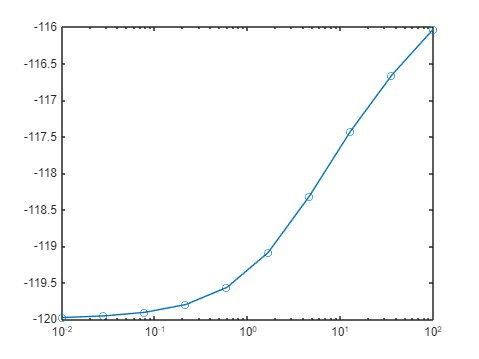

% plot(0:time_step:end_time, x_substrates_t, '-o')
% disp(mean(v_filaments_t))
semilogx(k_substrates, mean_v_filaments, '-o')